# Методы проверок случайных величин

## Проверка типа распределения

Проверка типа распределения случайных величин выполняется с помощью функций из Statistics and Machine learning Toolbox.

Создадим 2 вектора случайных величин:

- Равномерное распределение

- Нормальное распределение

uniform_numbers = rand(1,1e4);
normal_numbers = randn(1,1e4);

Построим гистограммы:

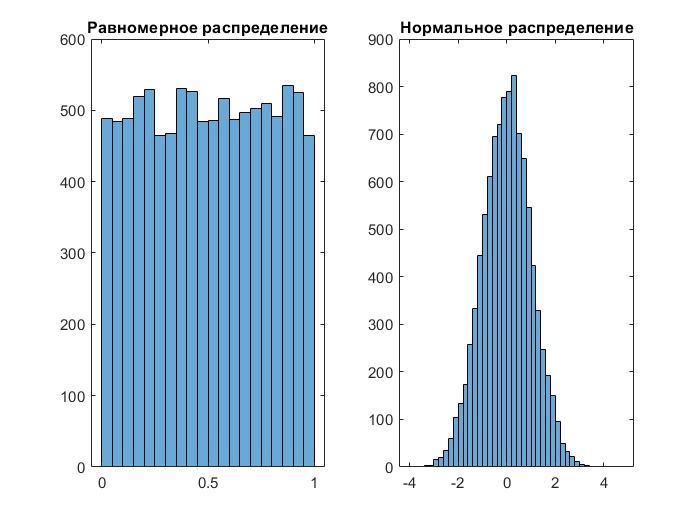

subplot(1,2,1)
histogram(uniform_numbers)
title('Равномерное распределение')
subplot(1,2,2)
histogram(normal_numbers);
title('Нормальное распределение')

### Проверка типов распределения

В общем случае, проверить тип распределения можно следующим образом:

Функция *makedist* создает требуемое распределение и записывет его в переменную **pd**, а функция *kstest* проверяет вектор **x **на соответсвие распределению **pd** при помощи опции *'cdf'*. В результате работы данной функции порождается булева переменная **h**, которая равно **логическому 0**, если гипотеза о характере распределения **верна**  

Проверим распределения созданных векторов:

u_d = makedist('uniform');
h_u = kstest(uniform_numbers,'cdf',u_d)

h_u = logical
   0


n_d = makedist('Normal');
h_n = kstest(normal_numbers,'cdf',n_d)

h_n = logical
   0

Однако, если ожидаемое распределение - нормальное, то достаточно воспользоваться функцией *jbtest*:

h = jbtest(normal_numbers)

h = 0

Обратите внимание, что тип возвращаемой величины - **double** а не **logical**

## Проверка диапазона величн

Для проверки диапазона векторов случайных величин можно использовать следующий подход:

где **upper_limit** - верхняя граница диапазона, а **lower_limit** - нижняя. Результат запишется в булеву переменную **in_range**, равную **ИСТИНА**, если вектор находится в требуемом диапазоне

Проверим, что вектор uniform_numbers находится в диапазоне $\left\lbrack 0\;1\right\rbrack$:

in_range = (max(uniform_numbers) <= 1) & (min(uniform_numbers) >= 0)

in_range = logical
   1

## Комбинирование проверок

Создвавать две отдельные проверки не требуется. Можно объединить проверки в одну:

Команда assert вернет ошибку если ее аргумент принимает значение **ЛОЖЬ**, таким образом проверка не пройдет:

u_d = makedist('uniform');
h_u = kstest(uniform_numbers,'cdf',u_d)

h_u = logical
   0

in_range = (max(uniform_numbers) <= 1) & (min(uniform_numbers) >= 0)

in_range = logical
   1

assert(~h_u & in_range)

Обратите внимание, что **результат** проверки типа распределения **необходимо инвертировать**!

**ВАЖНО**: В проверках ***assert*** не работатет. Используйте конструкцию вида